Test Case 1 


$$P(s) = \frac{(s-1)}{(s+2)(s^2+2s+5)}=\frac{b(s)}{a(s)}$$


- n = 2 （分母阶数）deg f(s) = 2

- 稳定零点阶数 deg bs(s) = 0

- k >= 2

syms s

b = [1 -1];
a = [1 4 9 10];
P = tf(b,a);


$$C_0 \left(s\right)=\frac{q\left(s\right)}{p\left(s\right)}$$


C0 = tf(pidtune(P,"PID"));
q = C0.num{1};
p = C0.den{1};
c = poly2sym(a,s)*poly2sym(p,s)+poly2sym(b,s)*poly2sym(q,s);
c = expand(c);

%%%%%
factoered = factor(c);
f = sym2poly(factoered(2));
h = sym2poly(factoered(1));
cpoly = sym2poly(c);
croots = roots(cpoly);


$$c\left(s\right)=a\left(s\right)p\left(s\right)+b\left(s\right)q\left(s\right)=f\left(s\right)h\left(s\right),\deg \left(f\right)=\deg \left(a\right),\deg \left(h\right)=\deg \left(p\right)$$



$$M\left(s\right)=\frac{a\left(s\right)}{f\left(s\right)},N\left(s\right)=\frac{b\left(s\right)}{f\left(s\right)},X\left(s\right)=\frac{p\left(s\right)}{h\left(s\right)},Y\left(s\right)=\frac{q\left(s\right)}{h\left(s\right)}$$


M = tf(a,f);
N = tf(b,f);
X = tf(P,h);
Y = tf(q,h);


$$Q_1 \left(s\right)=\frac{f\left(s\right)}{b_s \left(s\right)b_u \left(0\right)}\prod_{i=1}^k \frac{\alpha_i }{s+\alpha_i }$$



$$\frac{f\left(s\right)}{b_s \left(s\right)b_u \left(0\right)}$$


k = 2

k = 2

bs = 1;
bu = [0 -1];

bs = poly2sym(bs,s);
bu = poly2sym(bu,s);
leftHalf = tf(f,sym2poly(bs*bu));


$$\sum_{i=1}^k \frac{\alpha_i }{s+\alpha_i \;}$$


alpha_values = [100, 10];  % 明确的左半平面极点
num = 1;
denum = 1;
for i = 1:k
    num = num * alpha_values(i);
    denum = denum * (s + alpha_values(i));  % 注意是 s + α
end

% num = sym2poly(num);
denum = sym2poly(denum);
rihgtHalf = tf(num,denum);


$$Q_1 \left(s\right)=\frac{f\left(s\right)}{b_s \left(s\right)b_u \left(0\right)}\sum_{i=1}^k \frac{\alpha_i }{s+\alpha_i }$$


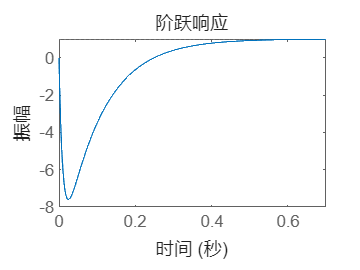

Q1 = series(leftHalf,rihgtHalf);
G = series(N,Q1);
step(G);